circles_img = imread("Circles.png");
coins_img = imread("Coins.png");
camera_img = imread("Cameraman.tif");
lighthouse_img = imread("Lighthouse.png");

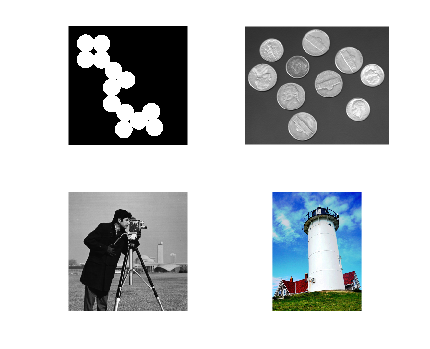

figure(1)
subplot(2,2,1);
imshow(circles_img);
subplot(2,2,2);
imshow(coins_img);
subplot(2,2,3);
imshow(camera_img);
subplot(2,2,4);
imshow(lighthouse_img)

[height, width, chans] = size(lighthouse_img)

height = 640

width = 480

chans = 3

disp(lighthouse_img(1:5,1:100, 1:3))


(:,:,1) =

  Columns 1 through 21

   11   11   11   11   13   14   11   11   14   15   17   17   17   15   16   14   13   11   10   10   12
   11   11   11   12   13   13   11   10   11   10   10   12   15   15   14   15   15   14   13   12   15
   15   14   13   15   15   15   15   13   12   12   10   11   12   12   10   12   14   15   16   15   17
   19   17   14   17   14   15   17   15   13   13   11   12   12   10   12   13   13   14   17   17   15
   17   16   18   17   15   15   14   15   14   11   11   10   10   11   11   12   14   16   19   21   20

  Columns 22 through 42

   14   13   11   10    9    7    9   13   16   17   14   13   16   19   21   21   20   19   18   17   17
   16   13   12   12   10   12   12   10   12   15   14   14   17   18   19   19   17   17   17   15   16
   15   13   12   12   12   14   13    8    9   13   12   13   15   16   17   16   13   14   16   14   13
   19   17   16   15   14   13   12   10   10   10   10   13   16   16   17   17   14   16


light_res = imresize(lighthouse_img, 3)

light_res = 1920×1440×3 uint8 array
light_res(:,:,1) =

    11    11    11    11    11    11    11    11    11    11    11    12    12    13    14    14    14    13    12    11    11    11    11    12    13    14    15    15    16    17    17    18    18    18    18    18    17    17    16    15    15    15    16    16    16    15    14    14    13    13    12    12    11    11    10    10    10    10    10    11    11    12    13    14    14    14    14    13    12    12    11    11    10    10    10     9     9     8     7     6     7     8     9    10    12    13    14    15    16    17    17    17    16    15    14    13    13    13    14    15    16    17    18    19    20    21    21    21    21    21    21    20    20    20    19    19    19    18    18    18    17    17    17    17    17    17    17    17    17    18    18    18    17    17    17    17    17    18    18    19    19    19    19    18    17    16    16    17    17    17    16    16    16    16    17    18    19  

hist = reshape(imhist(coins_img, 10), 1, [])

hist =            0         279       28655       21294        1334        2277        9891        7209        2326         535


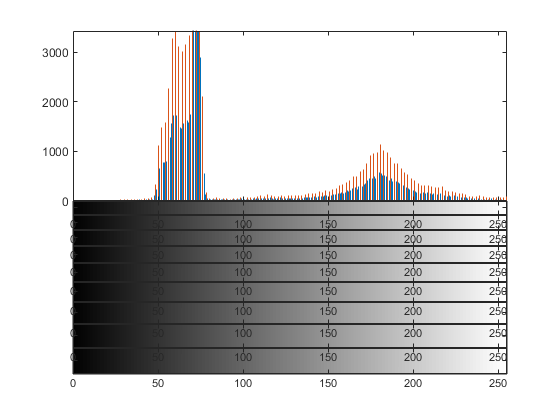



figure(2)
hold on
imhist(coins_img, 256)
imhist(coins_img, 128)
hold off